clear;

syms q1 q2 real;
syms q_dot_1 q_dot_2 real;
syms q_ddot_1 q_ddot_2 real;
syms m1 m2 real positive;
syms d_c_1 d_c_2 real positive;
syms I_c2_zz real positive;
syms U_2_max real;
syms A_2_max real positive;
syms T real positive;
syms alpha real positive;
syms t real positive;

M = [
    m1 + m2, -m2 * d_c_2 * sin(q2);
    -m2 * d_c_2 * sin(q2), I_c2_zz + m2 * d_c_2^2;
]

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & -d_{c,2}\,m_{2}\,\sin\left(q_{2}\right)\\ -d_{c,2}\,m_{2}\,\sin\left(q_{2}\right) & m_{2}\,{d_{c,2}}^{2}+I_{\mathrm{c2},\mathrm{zz}} \end{array}\right)$$

q_ddot = [q_ddot_1; q_ddot_2];

c = [-m2 * d_c_2 * cos(q2) * q_dot_2^2; 0]

$$c = \left(\begin{array}{c} -d_{c,2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$

U = M * q_ddot + c

$$U = \left(\begin{array}{c} -d_{c,2}\,m_{2}\,\cos\left(q_{2}\right)\,{{\dot{q}}_{2}}^{2}+{\ddot{q}}_{1}\,\left(m_{1}+m_{2}\right)-d_{c,2}\,m_{2}\,{\ddot{q}}_{2}\,\sin\left(q_{2}\right)\\ {\ddot{q}}_{2}\,\left(m_{2}\,{d_{c,2}}^{2}+I_{\mathrm{c2},\mathrm{zz}}\right)-d_{c,2}\,m_{2}\,{\ddot{q}}_{1}\,\sin\left(q_{2}\right) \end{array}\right)$$

u1 = simplify(U(1), Steps=1000)

$$u1 = -d_{c,2}\,m_{2}\,\cos\left(q_{2}\right)\,{{\dot{q}}_{2}}^{2}+{\ddot{q}}_{1}\,\left(m_{1}+m_{2}\right)-d_{c,2}\,m_{2}\,{\ddot{q}}_{2}\,\sin\left(q_{2}\right)$$

u2 = simplify(U(2), Steps=1000)

$$u2 = {\ddot{q}}_{2}\,\left(m_{2}\,{d_{c,2}}^{2}+I_{\mathrm{c2},\mathrm{zz}}\right)-d_{c,2}\,m_{2}\,{\ddot{q}}_{1}\,\sin\left(q_{2}\right)$$

u1 = subs(u1, [q_dot_1, q_ddot_1], [0, 0])

$$u1 = -d_{c,2}\,m_{2}\,\cos\left(q_{2}\right)\,{{\dot{q}}_{2}}^{2}-d_{c,2}\,m_{2}\,{\ddot{q}}_{2}\,\sin\left(q_{2}\right)$$

u2 = subs(u2, [q_dot_1, q_ddot_1], [0, 0])

$$u2 = {\ddot{q}}_{2}\,\left(m_{2}\,{d_{c,2}}^{2}+I_{\mathrm{c2},\mathrm{zz}}\right)$$

q_ddot_2_max = U_2_max / (I_c2_zz + m2 * d_c_2^2)

$$q\_ddot\_2\_max = \frac{U_{2,\max}}{m_{2}\,{d_{c,2}}^{2}+I_{\mathrm{c2},\mathrm{zz}}}$$

q_ddot_2 = piecewise(0 <= t <= T/2, A_2_max, T/2 <= t <= T, -A_2_max)

$$q\_ddot\_2 = \left\{ \begin{array}{cl} A_{2,\max} & \text{ if }2\,t\leq T\\ -A_{2,\max} & \text{ if }t\leq T\wedge T\leq 2\,t \end{array}\right.$$

q_dot_2 = piecewise(0 <= t <= T/2, A_2_max * t, T/2 <= t <= T, -A_2_max * (t - T))

$$q\_dot\_2 = \left\{ \begin{array}{cl} A_{2,\max}\,t & \text{ if }2\,t\leq T\\ A_{2,\max}\,\left(T-t\right) & \text{ if }t\leq T\wedge T\leq 2\,t \end{array}\right.$$

q_2 = piecewise(0 <= t <= T/2, 1/2 * A_2_max * t^2 - alpha, T/2 <= t <= T, -1/2 * A_2_max * (t - T)^2 + A_2_max * (T/2)^2 - alpha)

$$q\_2 = \left\{ \begin{array}{cl} \frac{A_{2,\max}\,t^{2}}{2}-\alpha & \text{ if }2\,t\leq T\\ \frac{A_{2,\max}\,T^{2}}{4}-\alpha -\frac{A_{2,\max}\,{\left(T-t\right)}^{2}}{2} & \text{ if }t\leq T\wedge T\leq 2\,t \end{array}\right.$$

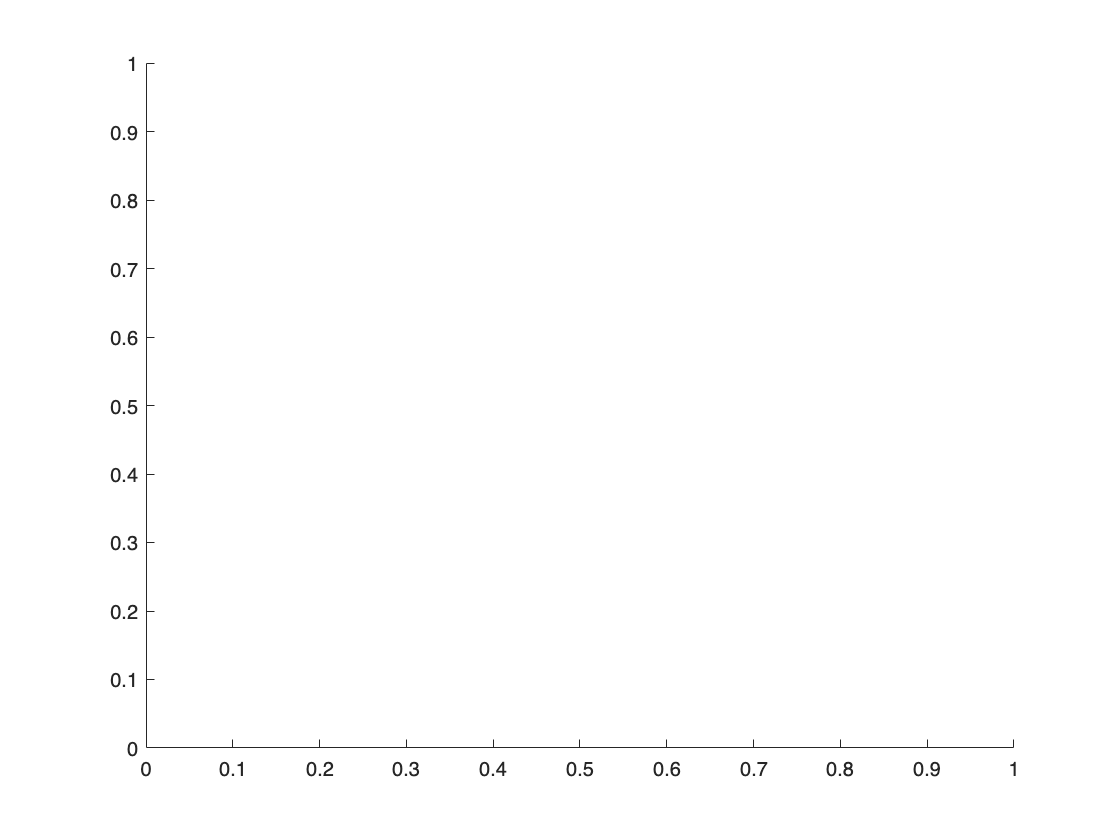

Error using fplot>singleFplot
Input must be a function or functions of a single variable.

Error in fplot>@(f1,f2)singleFplot(cax,{f1,f2},limits,extraOpts,args) (line 208)
        hObj = cellfun(@(f1,f2) singleFplot(cax,{f1,f2},limits,extraOpts,args),fn{1},fn{2},'UniformOutput',false);

Error in fplot>vectorize

fplot(q_ddot_2, t)

fplot(q_dot_2)
fplot(q2)
eq = A_2_max * T / 2 * T / 2 == 2 * alpha
solve(eq, T)